
$$\text{\textbf{Octave 2}}
\\
\begin{array}{lr} 
\text{Note} & \text{ Hz} \\
C & 65.4 \\ 
C\# & 69.3 \\
D & 73.4 \\
D\# & 77.8\\
E & 82.4\\
F & 87.3 \\
F\# & 92.5 \\
G & 98.0\\
G\# & 103.8\\
A & 110.0\\
A\# & 116.5\\
B & 123.5\\
\end{array}$$
                
$$\text{\textbf{Octave 3}}
\\
\begin{array}{lr} 
\text{Note} & \text{ Hz} \\
C & 130.8 \\ 
C\# & 138.6 \\
D & 146.8\\
D\# & 155.6\\
E & 164.8\\
F & 174.6 \\
F\# & 185.0 \\
G & 196.0\\
G\# & 207.7\\
A & 220.0\\
A\# & 233.1\\
B & 246.9\\
\end{array}$$
                
$$\text{\textbf{Octave 4}}
\\
\begin{array}{lr} 
\text{Note} & \text{ Hz} \\
C & 261.6 \\ 
C\# & 277.2 \\
D & 293.7\\
D\# & 311.1\\
E & 329.6\\
F & 349.2\\
F\# & 370.0\\
G & 392.0\\
G\# & 415.3\\
A & 440.0\\
A\# & 466.2\\
B & 493.9\\
\end{array}$$


Freq = 196;


Fs = 44100;
tf = 1;
Nt = 44100*tf;

tc = linspace(0,tf,Nt)';
yc = 0.2*sin(2*pi*Freq*tc);


Compute the Fourier series of the signal

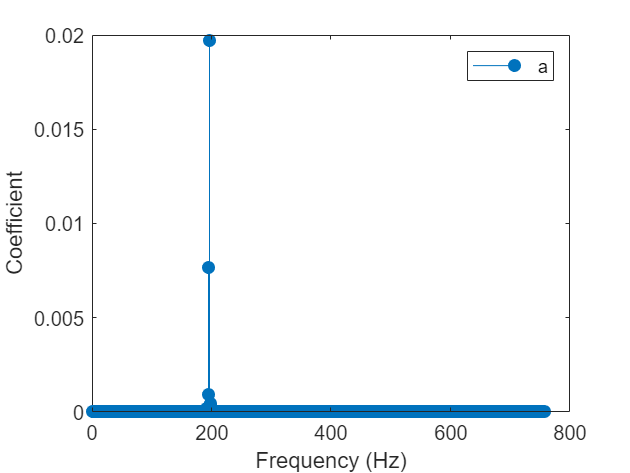

Nmodes = 1000; % Number of Fourier modes used in the estimation

a = zeros(1,Nmodes);
b = zeros(1,Nmodes);
a0 = 1/L*trapz(tc,yc);
for n = 1:Nmodes
    a(n) = 1/L*trapz(tc,cos(n*pi/L*tc).*yc);
    b(n) = 1/L*trapz(tc,sin(n*pi/L*tc).*yc);
end

% Frequencies
f = (1:Nmodes)/(2*L);

stem(f,b.^2 + a.^2,"filled")
xlabel("Frequency (Hz)")
ylabel("Coefficient")
legend("a","b")

Play the original sound

player = audioplayer(yc, Fs);
play(player);